# `Numerical Derivatives Group Assignment`

#### `Bethany Wu & Alex Stapely`

## `Problem 1: Finite Differences`

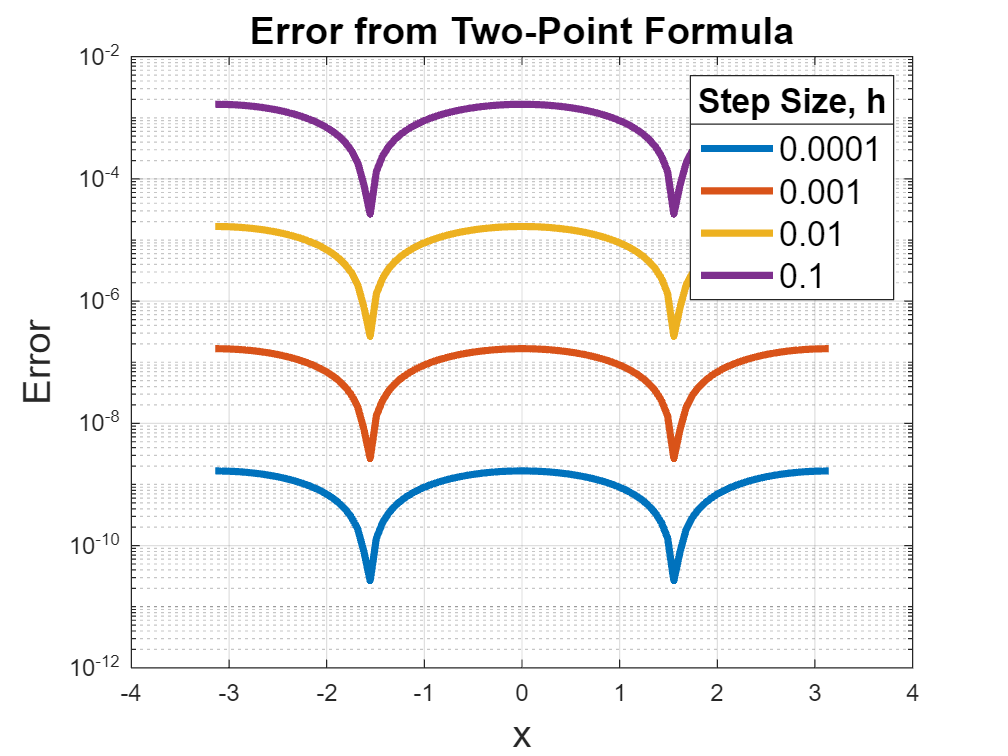

syms x0 h0
x = linspace(-pi,pi,100);
y = @sin;
dydx = @(x0,h0)  (y(x0+h0)-y(x0-h0))/(2*h0);

hs = [0.0001 0.001 0.01 0.1];
figure();
for h = hs
    yp = dydx(x,h);
    semilogy(x,abs(yp-cos(x)),'LineWidth',3); hold on;
end
title('Error from Two-Point Formula','FontSize',16); xlabel('x','FontSize',16); ylabel('Error','FontSize',16);
leg = legend(string(hs),'FontSize',14); title(leg,'Step Size, h'); grid on; hold off;

`Looking at the error plot, as h is decreased by an order of magnitude, the overall error of the derivative using the two-point formula us decreased by TWO orders of magnitude! When h = 1e-4, the error is in the range 1e-11 to 1e-9.`

## `Problem 2: More sophisticated derivatives...`

### `Part (a)`

`Richardson extrapolation of the finite difference formulas: Alex`

%Example use of Richardson extrapolation
f=@(x) sin(x);
% x = Point(s) to evaluate at
x = pi;
% Step
h = 0.4;
% Order of extrapolation 
n = 4;
der = richardson(f,x,h,n);
% Prints Result
fprintf('According to the Richardson extrapolation method, the derivative is: %.9f\n', der);

According to the Richardson extrapolation method, the derivative is: -0.999999998


`AD using dual numbers:`

`Chebyshev methods:`

## `Part (b)`

% %Write a driver function that allows you to use a common interface to apply the methods 
% % you implemented in part (a) with an arbitrary function. 
% 
% % Set up arbitrary function and parameters
% f=@(x) sin(x);
% % x = Point(s) to evaluate at
% x = pi;
% % Step
% h = 0.4;
% % Order of extrapolation 
% n = 4;

% % Calling that function here
% compare(f,x,h,n)

## `Part (c)`

% sin(x) for 100 points between -pi and pi
f=@(x) sin(x);
xs = linspace(-pi,pi,100);
h = 0.4;
n = 4;
compare(f,xs,h,n)

        -0.999999998467379
        -0.997986674067848
        -0.991954809565023
         -0.98192869314835
        -0.967948696449976
        -0.950071111982468
        -0.928367926468685
        -0.902926530976682
        -0.873849369026725
        -0.841253524087399
        -0.805270248121768
        -0.766044433082051
        -0.723734027480925
        -0.678509400388541
        -0.630552655416469
        -0.580056897450657
        -0.527225455086286
        -0.472271061895222
        -0.415414999823023
        -0.356886208164691
         -0.29692036170683
        -0.235758921748577
        -0.173648163822073
        -0.110838186027906
       -0.0475819019782461
        0.0158659775969535
        0.0792499704801515
         0.142314851703013
         0.204806681247209
         0.266473826571261
         0.327067975845992
         0.386345137818603
         0.444066624279309
         0.500000011174615
         0.553920074496793
         0.605609697181609
         0.654860743362048
 


% sin(1/x) for 100 points between [-1,1]
f2=@(x) 1/sin(x);
xs2 = linspace(-1,1,100);
h2 = 0.4;
n2 = 4;
compare(f2,xs2,h2,n2)

        -0.763084747262167
        -0.808091652702232
        -0.855641232214986
        -0.905968781246458
        -0.959335153206583
         -1.01603029191914
         -1.07637734121723
         -1.14073744355922
         -1.20951536491083
         -1.28316611528242
         -1.36220277539434
         -1.44720579298158
         -1.53883408152961
         -1.63783834603108
         -1.74507718407515
         -1.86153668092661
         -1.98835445805717
          -2.1268494865079
          -2.2785595125888
         -2.44528880344245
         -2.62917038917195
         -2.83274968344049
         -3.05910180029995
         -3.31200696137508
         -3.59623851304989
         -3.91810432737159
           -4.286676127296
          -4.7174113820821
         -5.24786600646539
         -6.08599757233338
         -4.79799454700737
         -6.47651815195187
         -7.38311425513489
         -8.33001645898104
         -9.38403491011454
         -10.5495115127053
         -11.7493215867267
 




% 3x^2 + 1/(pi^2)*ln((pi-x)^2)+1 for 100 points between [3.14,3.16]
f=@(x) 3*x^2 + 1/(pi^2)*log((pi-x)^2)+1;
xs = linspace(3.14,3.16,100);
h = 0.4;
n = 4;
compare(f,xs,h,n)

          54.4593448010866
          56.7693864582555
          59.4126852828065
          62.5146435789332
          66.2876269524735
          71.1363513021607
          77.9956979286096
          90.0527918600707
          122.059699937773
           86.716403610547
          76.8366207345404
          70.9232565876814
          66.7149901169713
          63.4606141814352
          60.8165392100525
          58.5966023278163
          56.6885227892932
          55.0193393135344
          53.5389579650401
          52.2114956589621
          51.0103679235785
          49.9153312995766
          48.9106154680552
          47.9836961906474
          47.1244621058956
          46.3246327894223
          45.5773423016944
          44.8768347782216
          44.2182377298296
          43.5973903999966
          43.0107118747541
          42.4550983848884
          41.9278423747832
          41.4265680265506
          40.9491793812341
          40.4938182146761
          40.0588295468465
 

## `Part (d)`

# `Functions`

function der  = richardson(f, x, h, n)
    R(1,1) = (f(x+h)-f(x))/h;
    for i = 1:n
        h = h/2;
        R(i+1,1)=(f(x+h)-f(x))/h;
        for j=1:i
            R(i+1,j+1)=(2^j*R(i+1,j)-R(i,j))/(2^j-1);
        end
    der = R(i+1,j+1);
    end
end

% This function is written for part b. Used to compare the different methods
% from part a 
function compare(arbitrary_function,xs,h,n)
    der_mat=zeros(100,1);
    for i = 1:100
        x = xs(i);
        der = richardson(arbitrary_function, x, h, n);
        % Put next function here 
        %fprintf('According to the Richardson extrapolation method, the derivative is: %.4f\n', der);
        % fprintf('According to the other method, the derivative is: %.9f\n', der);
        der_mat(i) = der;
    end
    disp(der_mat)
end